# Spike Triggered Averaging (STA) 

Here we want to explore how neurons respond to stimuli. We are going to construct a linear-nonlinear model to simulate the firing rate responses of a neuron in reaction to a time-varying noise stimulus. This model will include three main components: a linear filter, a thresholding nonlinearity, and a mechanism for spike generation. Our objective is to create each element of this model and produce a synthetic spike train. Subsequently, by utilizing the technique of spike-triggered averaging (STA), we will analyze this synthetic spike train to reconstruct and understand the receptive field of the neuron.

STA is a common method to determine the relationship between stimuli and neural response. It is frequently used in receptive field mapping. 

First of all let's simulate a neuron with a center-surround receptive field (RF). This is a typical structure in retina and thalamus (LGN). We can do that by subtracting two 2D Gaussian function: a narrow one for the center and a broader one for the surround. 

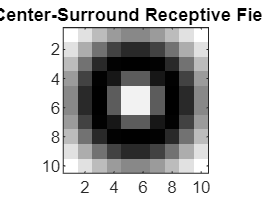

% Define the size of the receptive field
rfSize = 10; % Size of the receptive field
[x, y] = meshgrid(linspace(-5, 5, rfSize), linspace(-5, 5, rfSize));

% Define parameters for the Gaussians
centerSigma = 1; 
surroundSigma = 3;


% Create the center and surround Gaussians
centerGaussian = exp(-(x.^2 + y.^2) / (5 * centerSigma^2));
surroundGaussian = exp(-(x.^2 + y.^2) / (2 * surroundSigma^2));

% Create the receptive field by subtracting the surround from the center
receptiveField = centerGaussian - surroundGaussian;

% Plot the receptive field
figure;
imagesc(receptiveField);
colormap('gray');
axis image;
title('Center-Surround Receptive Field');

In the next step we generate a random noise stimulus to evoke some spikes from our neurons. Our neuron integrates luminance over space and time. Each pixel of the stimulus changes every milisecond so what we need to do is to multiply our Gaussian filter by stimulus at each time point and integrate our space and time. But let's break it down into two steps: first integration (convolutoin) over space and then over time. 

The stimulus is presented for 1000 ms i.e each pixel changes 1000 times independent of other pixels. 

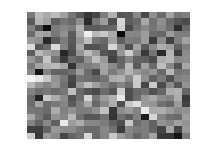

% Parameters
refreshRate = 1000; 
duration = 1; % Duration of the stimulus in seconds
screenSize = [20, 20];

% Total number of frames
numFrames = duration * refreshRate;

% Generate Gaussian white noise
noiseStimulus = randn([screenSize, numFrames]);

% Demonstrate the stimulus for the first 200 ms
for frame = 1:200
    imagesc(noiseStimulus(:, :, frame), [-3, 3]); % Displaying each frame
    colormap gray;
    axis off;
    pause(1 / refreshRate); % Pause to simulate
end

Now we need to pass the stimulus through our filter (RF structure) at each time point. Lets assum we know that RF is located at upper right quadrant of screen.  

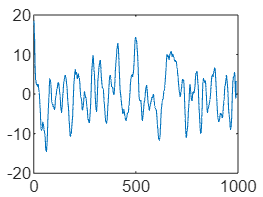

% windSize = 10;
% integWindow = [1:1:numFrames-windSize+1; windSize:1:numFrames]';
for frame_i = 1:size(noiseStimulus,3)
    integration_i = receptiveField .* noiseStimulus(1:10,11:20,frame_i);
    integrations(1,win_i) = sum(integration_i,'all');
end

% plot neuron response at each frame
plot(integrations);

xlabel('#Time Frame')
ylabel('Response Magnitude')


Up to this point we have seen how our neuron responds to spatial pattern of luminance but neurons also responde to temporal patterns. These filters help in processing visual information by emphasizing certain time-dependent aspects of the visual input. A neuron that integrates input signals over a fixed time period with equal weighting. We can represent such pattern with a kernel called boxcar kernel.

% Define the length of the kernel
kernelLength = 50;

% Create a time vector with 20 elements
t = linspace(-1, 1, kernelLength); % Evenly spaced 20 points between -1 and 1
boxcarKernel = double(abs(t) <= 0.5); % Boxcar kernel
plot(t, boxcarKernel);
title('Boxcar Kernel');
xlabel('Time');
ylabel('Amplitude');
ylim([0 2]);


Now let's convolve our temporal kernel with spatial respose of our neuron and called linear response (since then there would be a non-linear part also)

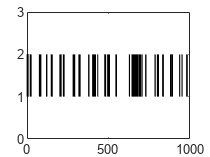

linResp = conv(integrations,boxcarKernel,'same');

plot(linResp)
hold on
plot(integrations)